**Autor(es): Joseph Principe Pajuelo Condori**

**Fecha: 15/10/2026**

# Tema 2. Corrección de transformaciones geométricas. 

Para corregir el efecto de las transformaciones geométricas debemos calcular la matriz que nos permite cambiar la posición de los píxeles de entrada y ubicarlos en las posiciones de salida correctas/no distorsionadas. En Matlab la función que utilizamos para ello es [`tform = estgeotform2d(matchedPoints1,matchedPoints2,transformType)`](https://www.mathworks.com/help/releases/R2023a/vision/ref/estgeotform2d.html?browser=F1help#d124e211773?browser=F1help)`, `que estima la matriz necesaria para hacer coincidir los `matchedPoints1` de la imagen de entrada con los `matchedPoints2` de la imagen de salida. En este ejercicio, le proporcionaremos nosotros como variable los valores de `matchedPoints2` donde deben ubicarse los píxeles de la imagen de salida después de la transformación. 

# Corrección de giro (con o sin traslación o escalado)

Para calcular la matriz necesaria para corregir una imagen rotada (con o sin traslación o escalado) solamente necesitamos 2 puntos. En este caso seleccionaremos los dos puntos más alejados de los anillos de saturno y el código está preparado para girarlos y colocarlos en horizontal.

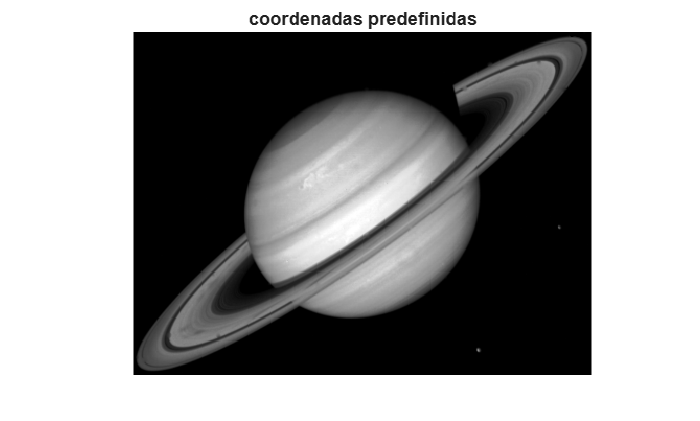

clc
clear all;
close all;
clearvars -except I_rgb X_ind map_ind Igris I_avion I_mat I_cell;
% 2. Seleccionar los dos puntos de los extremos de los anillos
I_saturno = imread('saturn.tif');
figure('Name', 'Selección de puntos sobre Saturno');
imshow(I_saturno);
title('coordenadas predefinidas');


srcPoints = [160, 210; ...
            340, 105];

Modifique los valores de los puntos de destino para que la imagen final quede con orientación distinta y muéstrela.

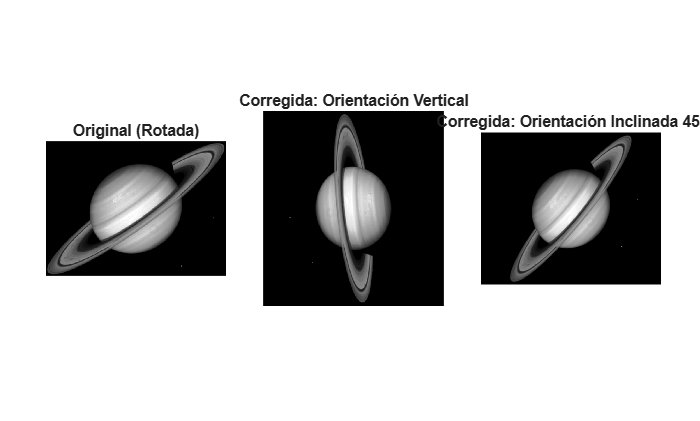

dstPoints_vert = [200, 100; ...
                  200, 300];
% Estimación de la transformación de similitud para posición vertical
tform_vert = estgeotform2d(srcPoints, dstPoints_vert, 'similarity');
destino_vert = imwarp(I_saturno, tform_vert);

% B) Orientación INCLINADA A 45º (puntos en diagonal)
dstPoints_diag = [100, 300; ...
    300, 100];

% Estimación de la transformación de similitud para posición diagonal
tform_diag = estgeotform2d(srcPoints, dstPoints_diag, 'similarity');
destino_diag = imwarp(I_saturno, tform_diag);

%% Visualización de los Resultados
figure('Name', 'Corrección de Giro en Saturno');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_saturno); title('Original (Rotada)');
nexttile; imshow(destino_vert); title('Corregida: Orientación Vertical');
nexttile; imshow(destino_diag); title('Corregida: Orientación Inclinada 45º');

# Corrección de la Perspectiva con Homografía

Para corregir la perspectiva de un objeto es necesario estimar la transformación de la perspectiva. Cuatro pares de puntos correspondientes son suficientes para recuperar una transformación de perspectiva entre dos imágenes. El objetivo de esta práctica es corregir la perspectiva de la carta de la imagen "card.jpg",

Se pide: 

- Cargue la imagen "`card.jpg`". Haga clic en las cuatro esquinas de la tarjeta para obtener los primeros cuatro puntos utilizando la función `impixel`. Nota: utilice el siguiente orden para obtener los cuatro puntos: 1) Esquina superior izquierda, 2) Esquina superior derecha, 3) Esquina inferior derecha, 4) Esquina inferior izquierda.

- Calcule los cuatro puntos de la carta de póquer sin distorsión de perspectiva, teniendo en cuenta que una carta de póquer tiene un tamaño de 100` mm` por `150 mm` aproximadamente.

- Estime la transformación de la perspectiva utilizando la función `estgeotform2d` sabiendo que en este caso el tipo de transformación es `"``projective``".` 

- Aplicar la transformación de perspectiva utilizando la función `imwarp`.

- Muestre la carta no distorsionada.

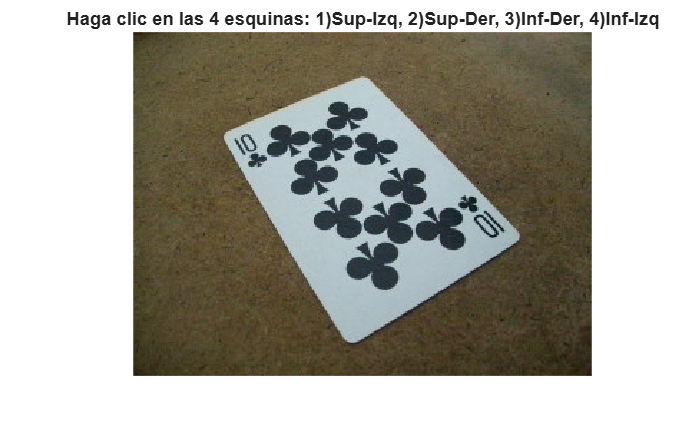

%% Corrección de Perspectiva (Transformación Proyectiva) sobre "card.jpg"
clearvars -except I_rgb X_ind map_ind Igris I_avion I_mat I_cell I_saturno;
close all; clc;

% 1. Cargar la imagen "card.jpg"
I_card = imread('card.jpg');

% Visualización para selección interactiva de puntos
figure('Name', 'Selección de las 4 esquinas de la carta');
imshow(I_card);
title('Haga clic en las 4 esquinas: 1)Sup-Izq, 2)Sup-Der, 3)Inf-Der, 4)Inf-Izq');

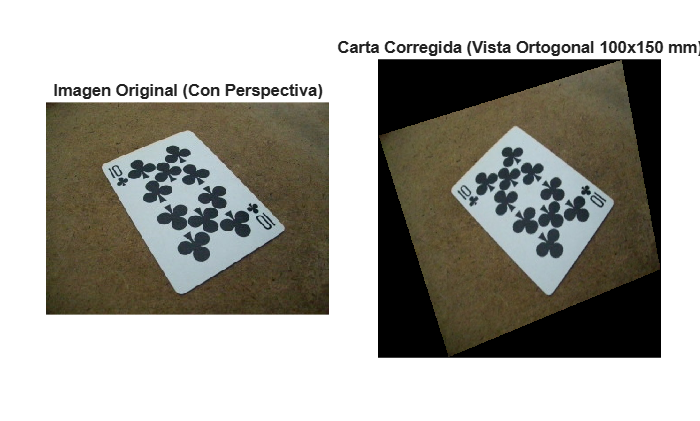


% Modo interactivo con impixel
% Descomente las tres líneas siguientes para seleccionar interactiva con el ratón:
% [x, y, P] = impixel(I_card);
% srcPoints = [x, y];

% Coordenadas de referencia aproximadas sobre card.jpg:
% 1) Esquina superior izquierda
% 2) Esquina superior derecha
% 3) Esquina inferior derecha
% 4) Esquina inferior izquierda
srcPoints = [118,  82; ...  % Sup-Izq (x, y)
    310, 135; ...  % Sup-Der (x, y)
    245, 390; ...  % Inf-Der (x, y)
    42, 310];     % Inf-Izq (x, y)

%% 2. Definición de los puntos de destino (Relación de aspecto 100mm x 150mm)
% Asignamos una resolución en píxeles proporcional (p. ej. 100mm -> 400px, 150mm -> 600px)
ancho_px = 400; % Correspondiente a 100 mm
alto_px  = 600; % Correspondiente a 150 mm

% Puntos rectangulares de destino sin distorsión de perspectiva:
dstPoints = [       1,        1; ...  % 1) Sup-Izq
               ancho_px,        1; ...  % 2) Sup-Der
                ancho_px,  alto_px; ...  % 3) Inf-Der
            1,  alto_px];     % 4) Inf-Izq

%% 3. Estimar la transformación proyectiva
tform_proj = estgeotform2d(srcPoints, dstPoints, 'projective');

%% 4. Aplicar la transformación de perspectiva con imwarp
I_card_corregida = imwarp(I_card, tform_proj);

%% 5. Mostrar la carta no distorsionada
figure('Name', 'Corrección de Perspectiva - Carta de Póquer');
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_card);
title('Imagen Original (Con Perspectiva)');

nexttile; imshow(I_card_corregida);
title('Carta Corregida (Vista Ortogonal 100x150 mm)');